# **スポーツ統計学演習 Week 1**

## 乱数の生成

% 離散一様分布: randi
% 例． サイコロを振ったとき、1から6までの整数の目が均等に出る
iMax = 6 ; % [1, imax] の区間に含まれる整数から乱数を生成
n = 100 ;   % サンプルサイズ

x1 = randi(iMax, [n,1])

x1 =      1
     4
     1
     4
     1
     4
     4
     1
     6
     2


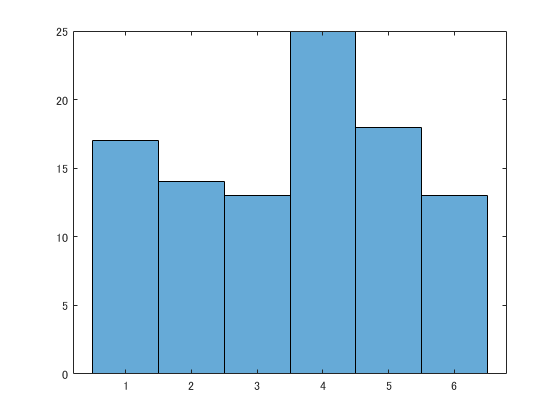


figure
histogram(x1)



% 連続一様分布: rand
% rand 関数は、区間(0,1)の一様分布乱数を生成する
n = 100 ;
xMax = 5 ;

x2 = rand([n,1]) * xMax

x2 =     2.8540
    3.7534
    2.7671
    1.1197
    0.6493
    0.0185
    4.6165
    0.5541
    1.9626
    3.9840


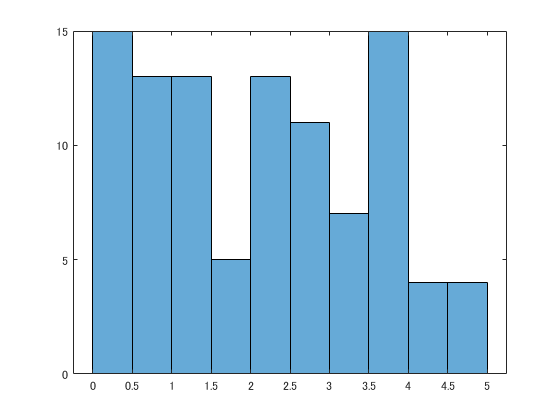


figure
nBin = 10 ;
histogram(x2, nBin)



% 正規分布：　randn
% randn 関数は、平均: 0, 標準偏差: 1 の標準正規分布乱数を生成する
n = 100 ;
mu = -1 ;
sigma = 2 ;

x3 = mu + randn([n,1])*sigma

x3 =     0.7390
   -5.7335
    3.6587
   -1.3214
    3.2265
   -0.9144
   -0.7685
    0.6222
   -1.6288
   -1.3470


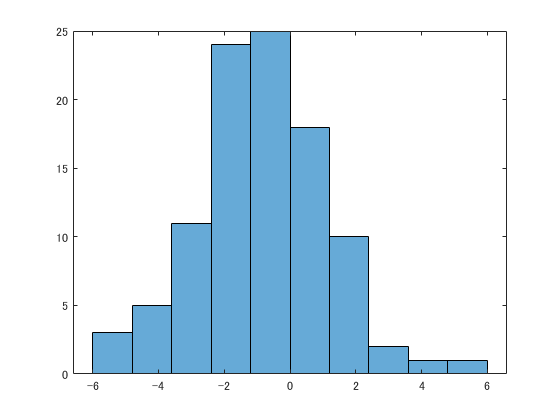


figure
nBin = 10 ;
histogram(x3, nBin)

## 中心極限定理

例

サイコロを k 回投げて、出た目の平均値を計算する

この試行を n 回繰り返した時、"出た目の平均値" はどのような分布となるか？

% サイコロを k 回投げて、出た目の平均値を計算する
k = 30 ;
n = 100000 ;

xx1 = randi(6, [k,n]) 

xx1 =      6     6     4     4     1     5     4     5     6     4     4     3     1     1     2     6     1     6     4     6     1     3     4     5     4     5     1     4     1     5     1     3     3     5     1     6     5     6     3     4     3     3     6     3     3     4     2     4     4     2
     1     6     2     6     5     4     5     1     4     4     6     2     6     1     3     4     6     4     6     5     4     5     1     1     4     1     5     1     2     3     6     4     6     1     6     5     3     4     1     6     5     2     6     5     6     3     4     5     3     1
     6     2     3     6     4     4     2     6     6     5     5     6     3     5     1     1     4     6     5     3     6     6     3     4     4     1     4     3     6     3     6     4     1     4     3     5     4     3     2     1     3     2     4     5     6     4     2     5     5     4
     4     3     5     2     6     6     1     4     3     4     2     1     4     5     6 

xbar = mean(xx1)

xbar =     4.3667    3.3000    3.5000    3.7000    3.4000    2.9000    3.4667    2.8667    3.8667    3.1333    3.5667    3.7000    3.3667    3.1333    2.9667    3.4667    3.3333    3.4000    4.1000    3.1333    3.2667    3.9333    3.4000    3.5333    3.6000    3.3000    3.7667    3.3333    3.5667    2.9333    3.3333    3.0667    3.6667    3.6000    3.8333    3.3333    3.4333    3.4000    3.5000    3.6333    3.1000    3.8667    3.5667    3.7000    4.0000    3.3000    2.8667    3.3667    3.5000    3.3333


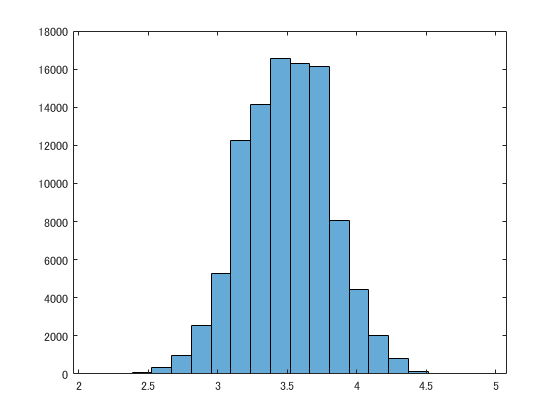


figure
nBin = 20 ;
histogram(xbar, nBin) ;


% ここで、母集団は、[1,6]の整数値をとる離散一様分布である
% 標本を抽出する母集団の、平均値と分散は以下の通り
popAvr = (1+6)/2

popAvr = 3.5000

popAvr = mean([1:6]) 

popAvr = 3.5000

popVar = (6^2-1)/12

popVar = 2.9167

popVar = var([1:6],1)

popVar = 2.9167

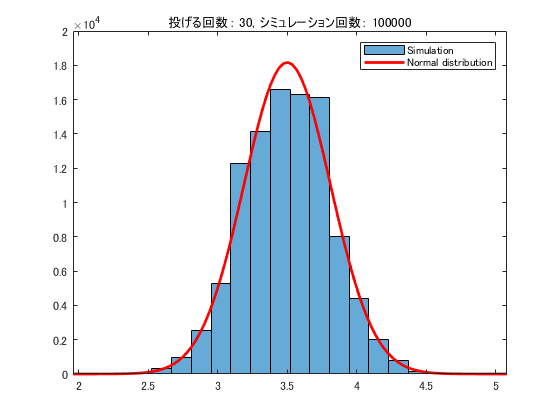


figure
nBin = 20 ;
h = histogram(xbar, nBin) ;
hold on

temp = get(gca, 'xlim') ; 
xx = linspace(temp(1), temp(2), 100) ;
y = pdf('normal', xx, popAvr, (popVar/k)^0.5) ;
plot(xx, y*(n*h.BinWidth), 'r-', 'linewidth', 2) ;
title(sprintf('投げる回数： %d, シミュレーション回数： %d', k, n))
legend({'Simulation','Normal distribution'})